clear
addpath("frffit"); addpath("Assignments"); addpath("Assignment 3")

M = 0.05;
m = 0.04;
b = 0.02;
g = 9.81;
L = 0.15;

H = tf([1 0],[-1/6*(4*M+m)*L^3, -2/3*L*b, g*(M+m), g*b])

H =
 
                       -s
  --------------------------------------------
  0.000135 s^3 + 0.002 s^2 - 0.8829 s - 0.1962
 
Continuous-time transfer function.
Model Properties


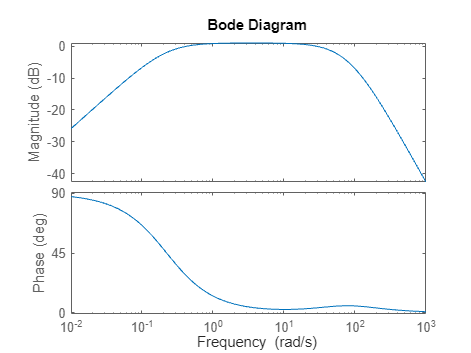

bode(H)

pole(H)

ans =   -88.5151
   73.9224
   -0.2221



C1 = tf([1],[1])

C1 =
 
  1
 
Static gain.
Model Properties


C2 = tf([-0.55],[1])

C2 =
 
  -0.55
 
Static gain.
Model Properties


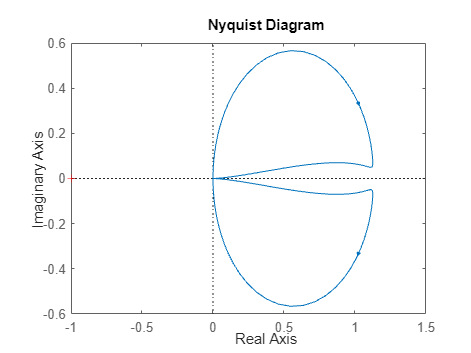

nyquist(C1*H)

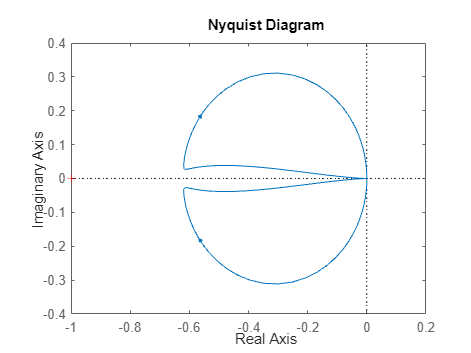

nyquist(C2*H)

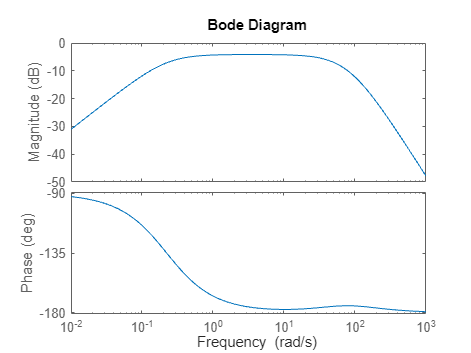

bode(C2*H)

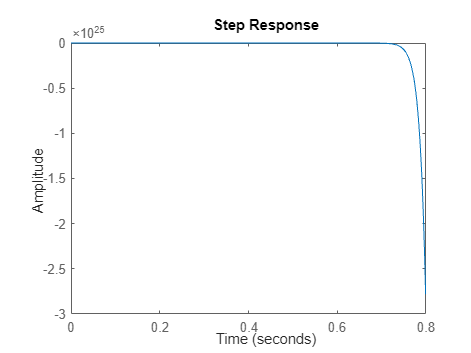

step(H)

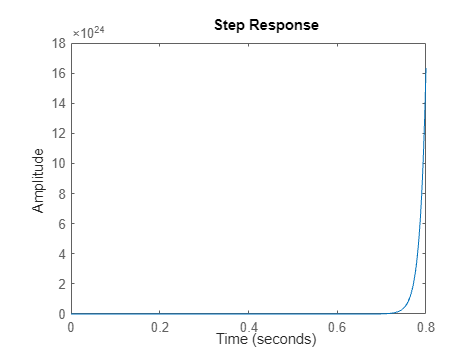

step(C2*H)

P = 0.5

P = 0.5000


C3 = tf([P],[1 1])

C3 =
 
   0.5
  -----
  s + 1
 
Continuous-time transfer function.
Model Properties


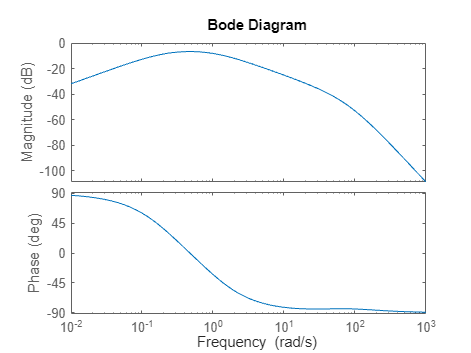

bode(C3*H)

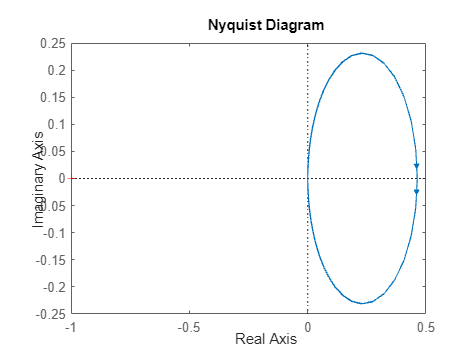

nyquist(C3*H)